MATLAB

Representação do gráfico de funções reais de duas variáveis reais

clear

Abordagem numérica na representação do gráfico de funções reais de duas variáveis reais. Gráfico a três dimensões (3D).

% uso das funções "meshgrid" e "surf"
% doc meshgrid
% doc surf

descrição com dois pontos:

define-se o vetor $vx = [ x(1) \; x(2) ]$ das abcissas de dois pontos do gráfico da função

define-se o vetor $vy = [ y(1) \; y(2) ]$ das ordenadas dos dois pontos do gráfico

a instrução $[x \, y ] = \mathrm{meshgrid}(vx,vy)$ define a malha de pontos $(x,y)$ de coordenadas


$$(x(1),y(1))$$
    
$$(x(2),y(1))$$



$$(x(1),y(2))$$
    
$$(x(2),y(2))$$


% exemplo
% representação do gráfico da função z = x^2 + y - x
% na região retangular definida pelos pontos (x,y) tais que
% -2 <= x <= 2, -1 <= y <= 1

% definiçao dos pontos de R3
vx = linspace(-2,2,2)       % vetor das abcissas

vx =     -2     2


vy = linspace(-1,1,2)       % vetor das ordenadas

vy =     -1     1


[x,y] = meshgrid(vx,vy);    % malha a 2D
[x,y]

ans =     -2     2    -1    -1
    -2     2     1     1


% vetor das cotas associado à função z = x^2 + y - x
z = x.^2 + y - x

z =      5     1
     7     3


a última instrução permite determinar 

as cotas dos pontos $(x,y,z)$ de R3

de coordenadas


$$(x(1),y(1),z1)$$
    
$$(x(2),y(1),z3)$$



$$(x(1),y(2),z2)$$
    
$$(x(2),y(2),z4)$$


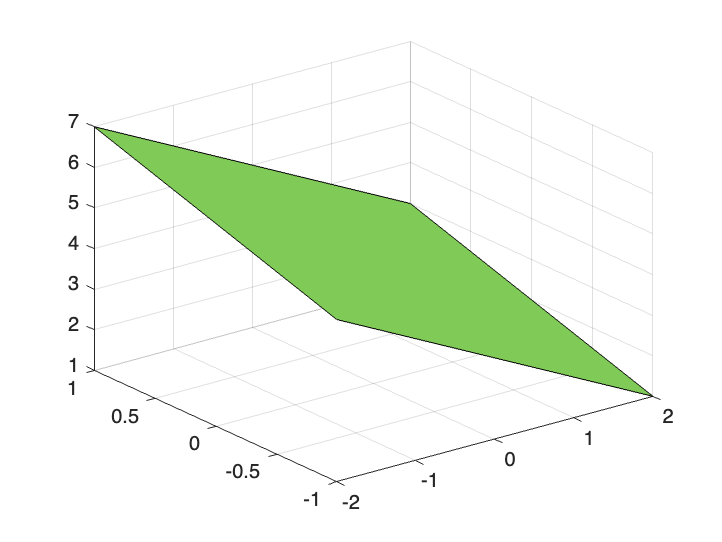

% doc surf
surf(x,y,z) % gráfico da superfície

a última instrução $\mathrm{surf}(x,y,z)$ permite representar 

os pontos de coordenadas


$$(x(1),y(1),z1)$$
    
$$(x(2),y(1),z3)$$



$$(x(1),y(2),z2)$$
    
$$(x(2),y(2),z4)$$


definindo um polígono ou vários polígonos retangulares

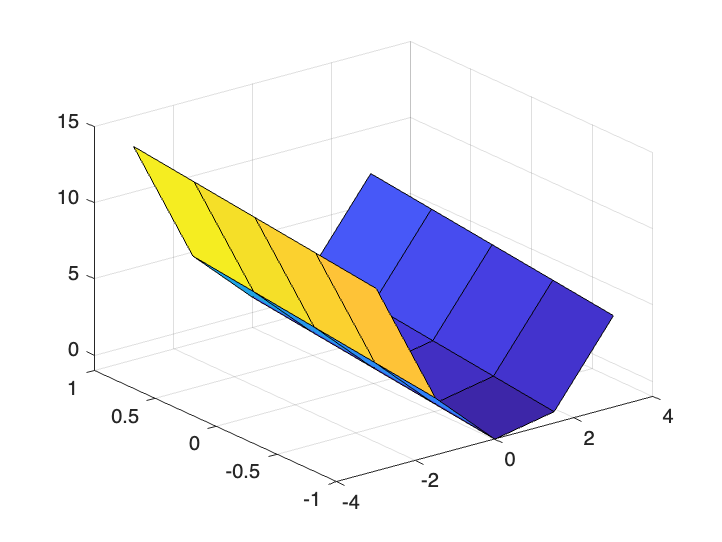

% aumentando o número de pontos - amostra de 25 pontos
vx = linspace(-3,3,5);      % vetor das abcissas
vy = linspace(-1,1,5);      % vetor das ordenadas
[x,y] = meshgrid(vx,vy);    % malha a 2D
z = x.^2 + y - x;           % vetor das cotas
surf(x,y,z)                 % plot da superfície

Exercício

Representar o gráfico da função 


$$f(x,y)=x^2+y^2$$
 

na região retangular 


$$R=\{(x,y) \in\mathbb{R}^2 : -2\leq x\leq 2 \, \wedge \, -2\leq y\leq 2\}$$


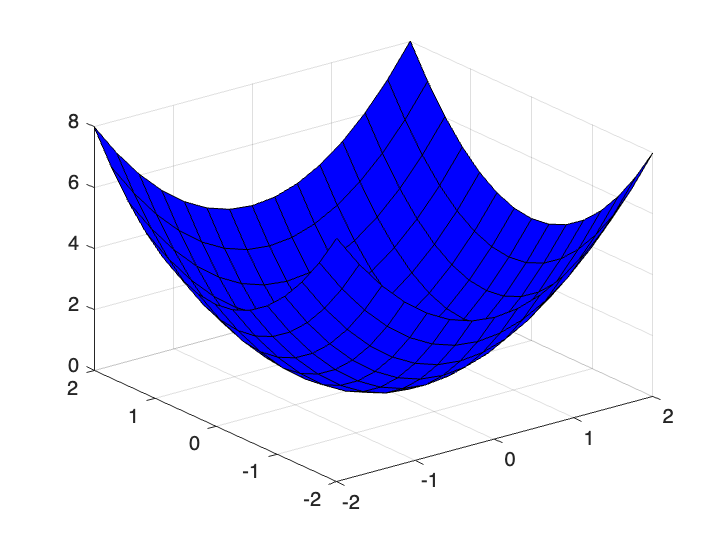

vx = linspace(-2,2,15);
vy = linspace(-2,2,15);
[x,y] = meshgrid(vx,vy);

z = x.^2 + y.^2;
surf(x,y,z)

colormap([0 0 1])

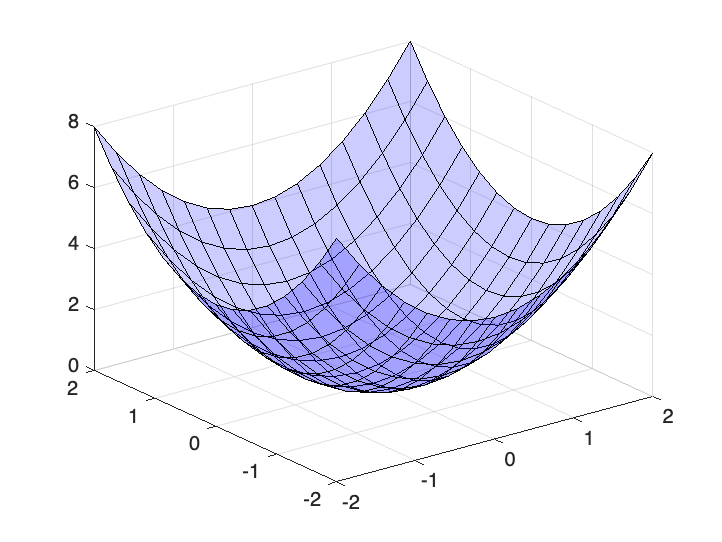

% usando algumas opções da função "surf"
surf(x,y,z,'FaceAlpha',0.2)

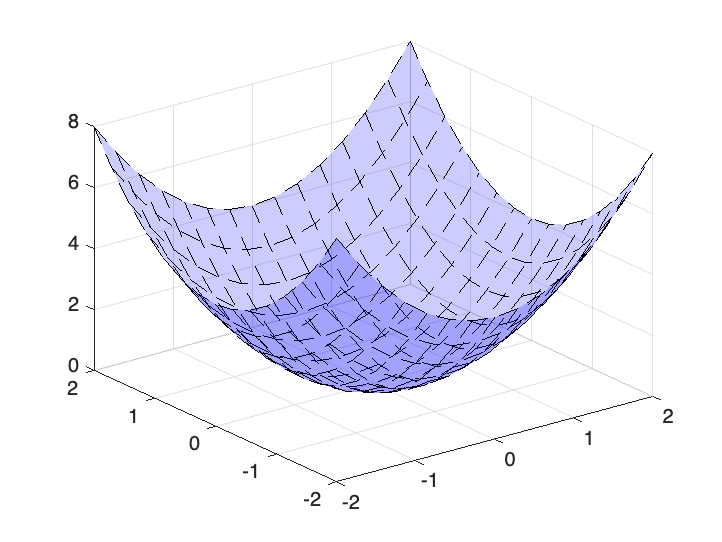

surf(x,y,z,'FaceAlpha',0.2,'LineStyle','--')

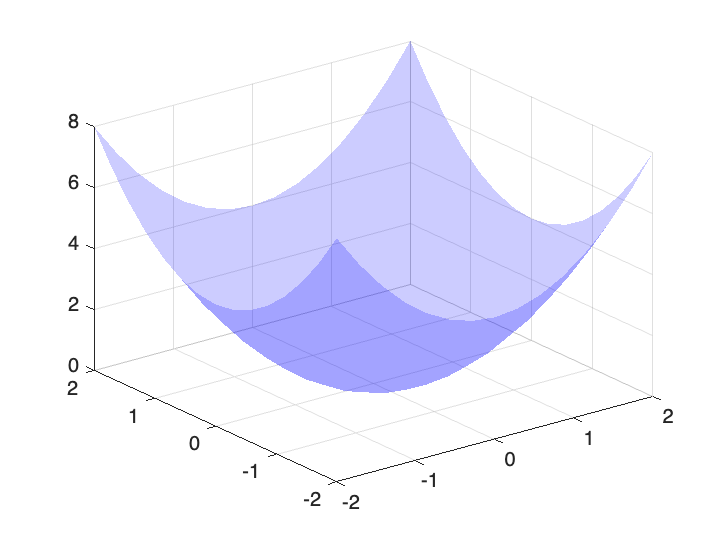

surf(x,y,z,'FaceAlpha',0.2,'EdgeColor','none')

Outras representações

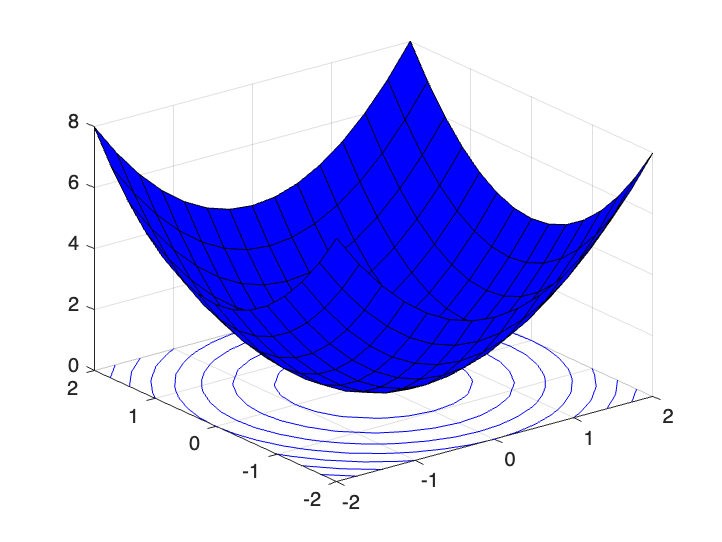

% doc surfc 
surfc(x,y,z)

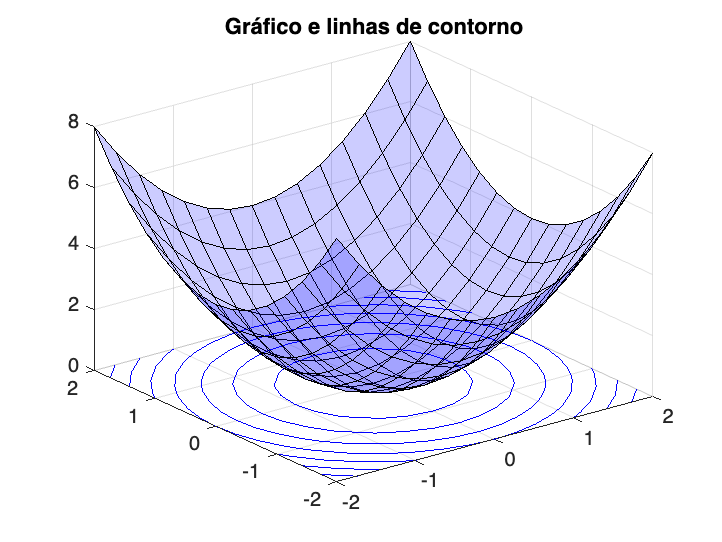


surfc(x,y,z,'FaceAlpha',0.2)
title('Gráfico e linhas de contorno')

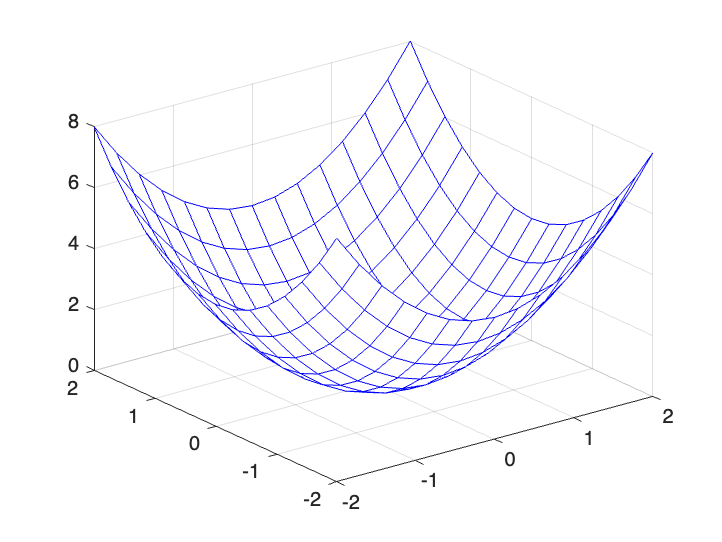


% doc mesh
mesh(x,y,z)

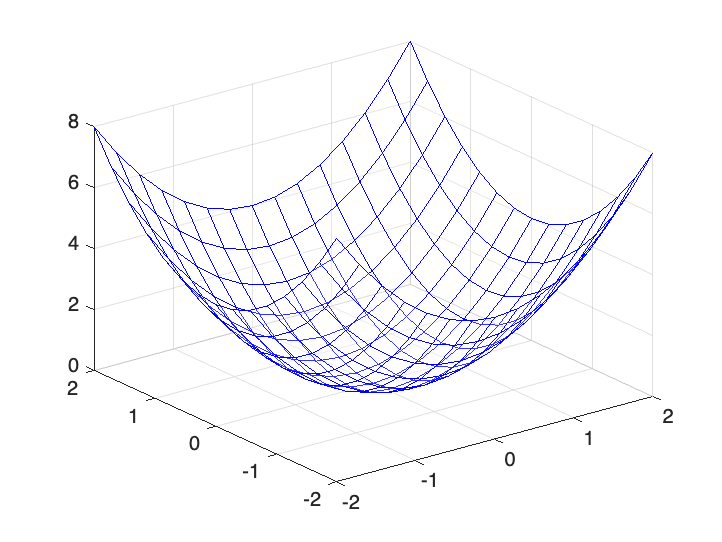


mesh(x,y,z,'FaceAlpha',0.2)

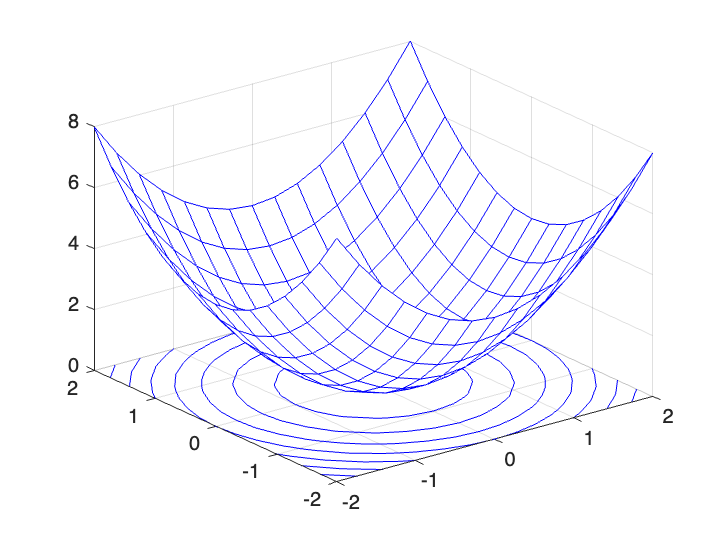


% doc meshc
meshc(x,y,z)

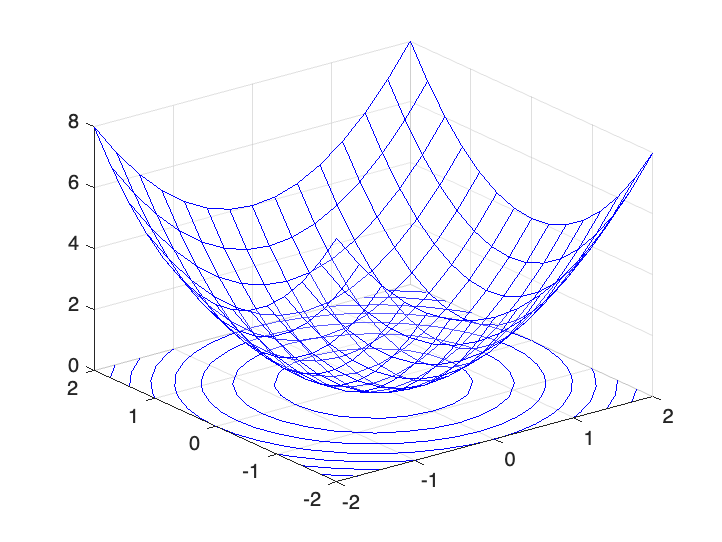


meshc(x,y,z,'FaceAlpha',0.2)

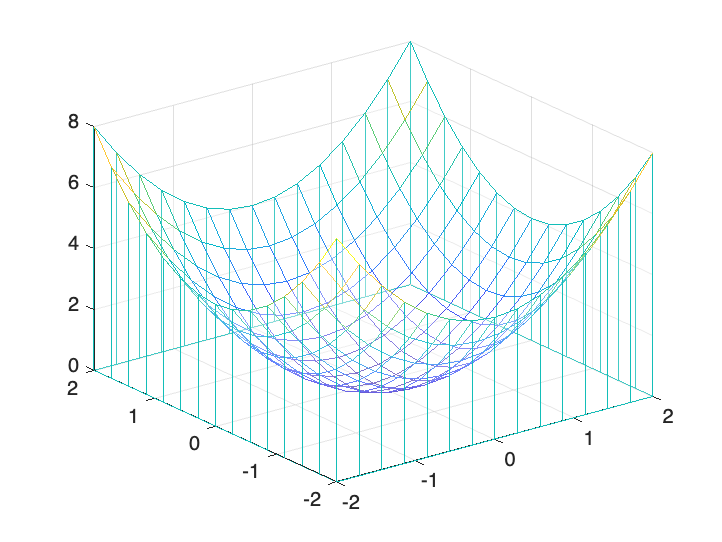


% doc meshz
meshz(x,y,z,'FaceAlpha',0.2)

colormap default

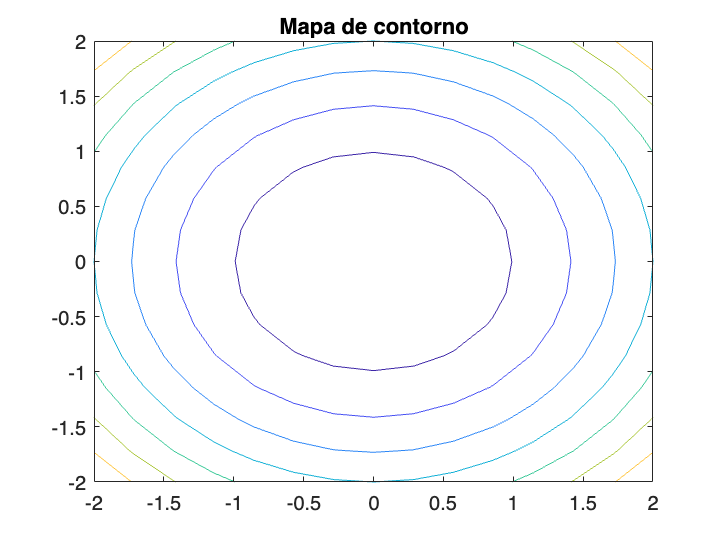


% doc contour
contour(x,y,z)
title('Mapa de contorno')